# Testing McCabe Complexity

This test can be used to qualify that the contents of a MATLAB project do not have exceedingly large cyclomatic complexity which can be a source of bugs.

## Use Interactively

To use interactively, while a MATLAB project is open, simply run the tests or create a TestSuite from the class and run it.

run(tMcCabeComplexity)

If it fails, the offending file information will be returned:

run(tMcCabeComplexity)

Running tMcCabeComplexity
.
Done tMcCabeComplexity
__________



ans =   TestResult with properties:

          Name: 'tMcCabeComplexity/shouldHaveLowComplexity'
        Passed: 1
        Failed: 0
    Incomplete: 0
      Duration: 0.4101
       Details: [1×1 struct]
Totals:
   1 Passed, 0 Failed, 0 Incomplete.
   0.4101 seconds testing time.

## Using In Project

To use this test in automated workflows, simply add it to your MATLAB project and label it as "Test".  When a TestSuite is created from the project, it will be included.  If a file in the project is modified to be too complexity, it will fail the build as a result.

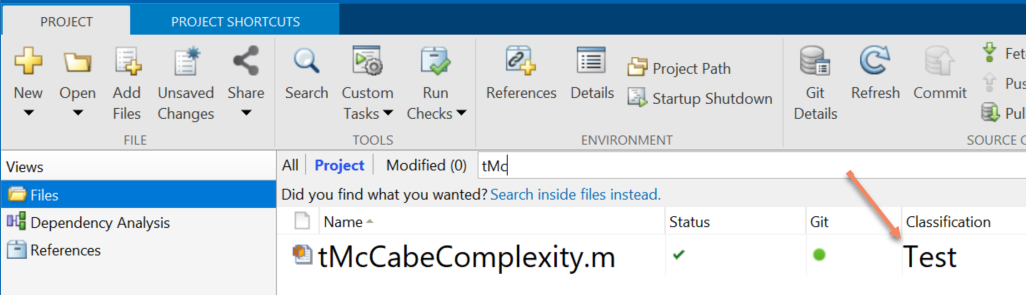

TS = matlab.unittest.TestSuite.fromProject(currentProject)

Running tMcCabeComplexity

Verification failed in tMcCabeComplexity/shouldHaveLowComplexity.
    ----------------
    Test Diagnostic:
    ----------------
    McCabe Complexity of 215
    In: C:\Documents\MATLAB\Content\demos\HumanActivityRecognition\HelperFunctions\nhist.m
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyLessThan failed.
    --> The value must be less than the maximum value.
    
    Actual Value:
       215
    Maximum Value (Exclusive):
        10
    ------------------
    Stack Information:
    ------------------
    In C:\Documents\MATLAB\TestMcCabeComplexity\tMcCabeComplexity.m (tMcCabeComplexity.shouldHaveLowComplexity) at 34

ans =   TestResult with properties:

          Name: 'tMcCabeComplexity/shouldHaveLowComplexity'
        Passed: 0
        Failed: 1
    Incomplete: 0
      Duration: 2.1010
       Details: [1×1 struct]
Totals:
   0 Passed, 1 Failed (rerun), 0 Incomplete.
   2.101 seconds testing time.

run(TS)

*Copyright 2020 The MathWorks, Inc.*